# Assignment 4

Miranda Pietraski, Gia-Uyen Tran, Jiayuan Liu

**1. Frequency domain filtering. **Do the following for 2 images of your choice **(10 points each for all sub-parts = 30 points total)**

- Apply low pass filtering by multiplication in frequency domain. Show filtered image in spatial domain.

- Apply high pass filtering by multiplication in frequency domain. Show filtered image in spatial domain.

- Add noise to your images. Does spatial domain filtering (median filtering, spatial domain gauss filter, etc.) work better to remove this noise or frequency domain filtering?

%**Setup**

% Image 1: Miranda
miranda = imread('../images/IMAGE012.jpg');
miranda = miranda(:,301:1500,:);
%imshow(miranda);   // initial image 
mg = im2gray(miranda);
% imshow(mg,[])     // grayscale image

% Freq Domain
Y = fft2(mg, 1200, 1200);
Y1 = abs(Y);
Y2 = log(abs(Y));
Y3 = log(abs(fftshift(Y)));
% imshow(Y3, []);   // freq domain image


% Image 2: Computer
pc = imread('../images/IMAGE001.jpg');
pc = pc(:,51:530,:);
%imshow(pc);   // initial image 
mg_pc = im2gray(pc);
% imshow(mg_pc,[])     // grayscale image

% Freq Domain
Y_pc = fft2(mg_pc, 480, 480);
Y1_pc = abs(Y_pc);
Y2_pc = log(abs(Y_pc));
Y3_pc = log(abs(fftshift(Y_pc)));
% imshow(Y3_pc, []);   // freq domain image


% First Image Low Freq Filter
s = 1200;
[filteredmg,gaussion_low_mg] = LPFilter(60, Y, s);

figure
imshow(gaussion_low_mg,[])

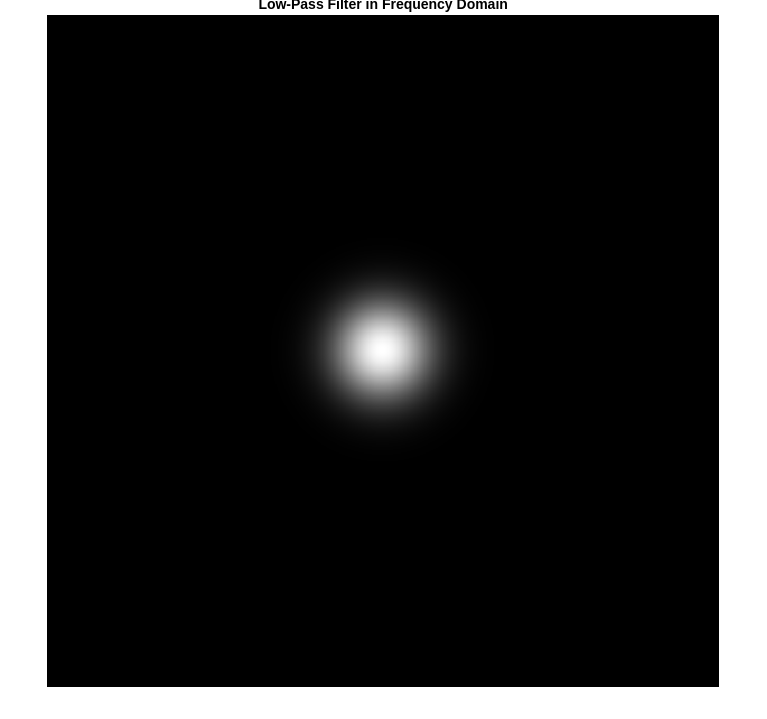

title("Low-Pass Filter in Frequency Domain")


figure
subplot(1,2,1)
imshow(mg, [])
title("Inital Grayscale Image")
subplot(1,2,2)
imshow(filteredmg, [])

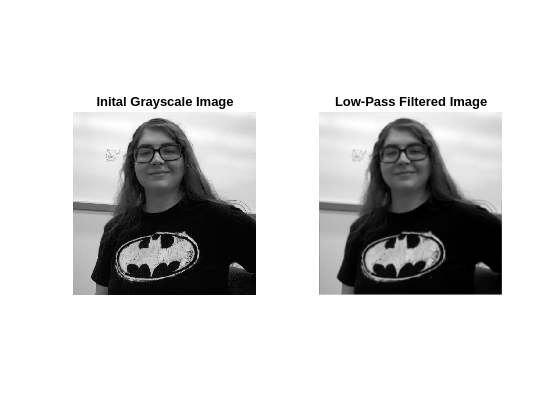

title("Low-Pass Filtered Image")

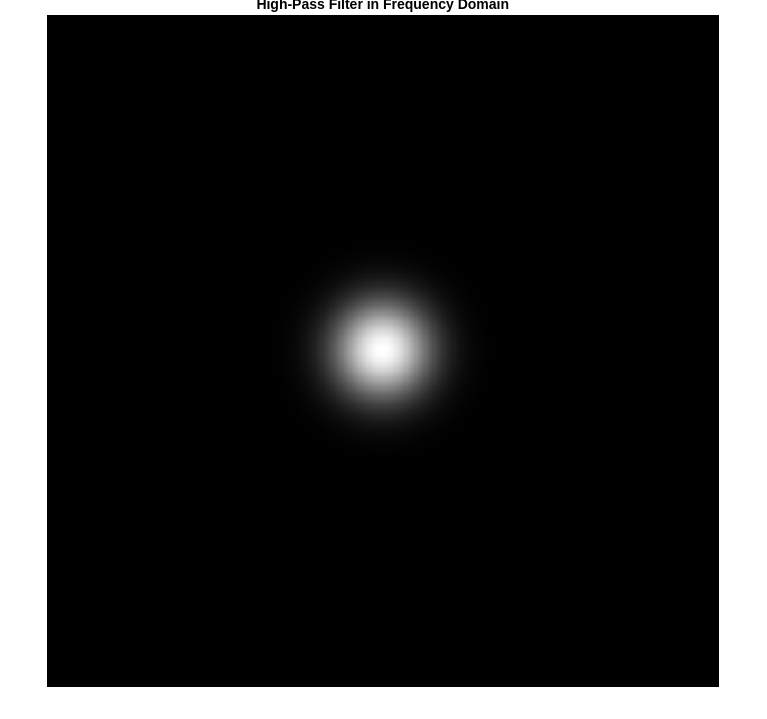


% First Image High Freq Filter
[filteredmg_high,gaussion_high_mg] = HPFilter(60, Y, s);

figure
imshow(gaussion_high_mg,[])
title("High-Pass Filter in Frequency Domain")


figure
subplot(1,2,1)
imshow(mg, [])
title("Inital Grayscale Image")
subplot(1,2,2)
imshow(filteredmg_high, [])

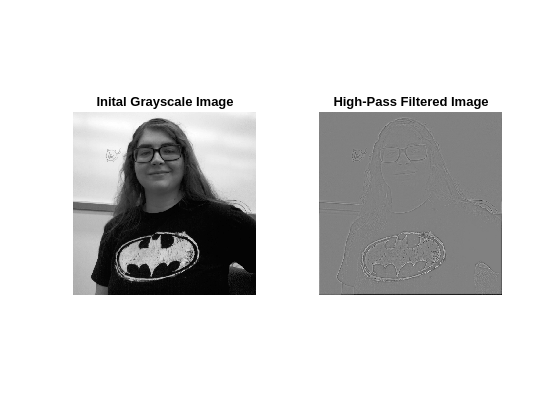

title("High-Pass Filtered Image")

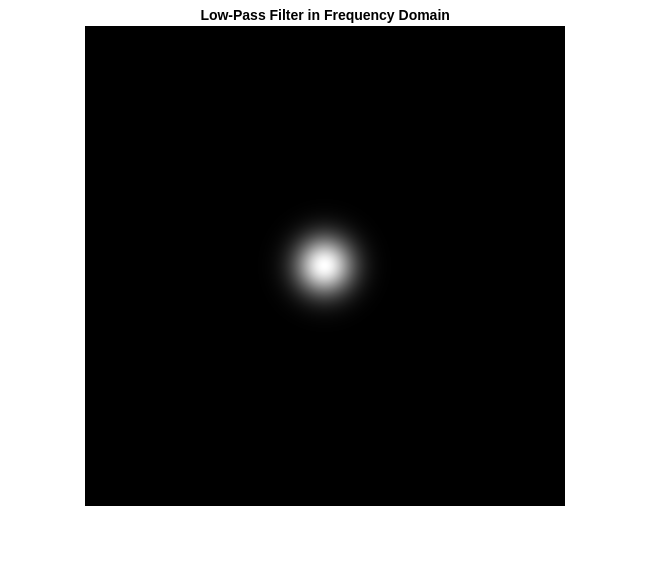

% Second Image Low Freq Filter
s2 = 480;
[filteredmg2,gaussion_low_mg2] = LPFilter(20, Y_pc, s2);

figure
imshow(gaussion_low_mg2,[])
title("Low-Pass Filter in Frequency Domain")


figure
subplot(1,2,1)
imshow(mg_pc, [])
title("Inital Grayscale Image")
subplot(1,2,2)
imshow(filteredmg2, [])

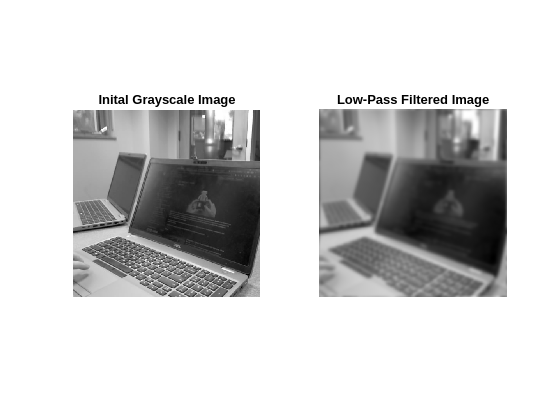

title("Low-Pass Filtered Image")

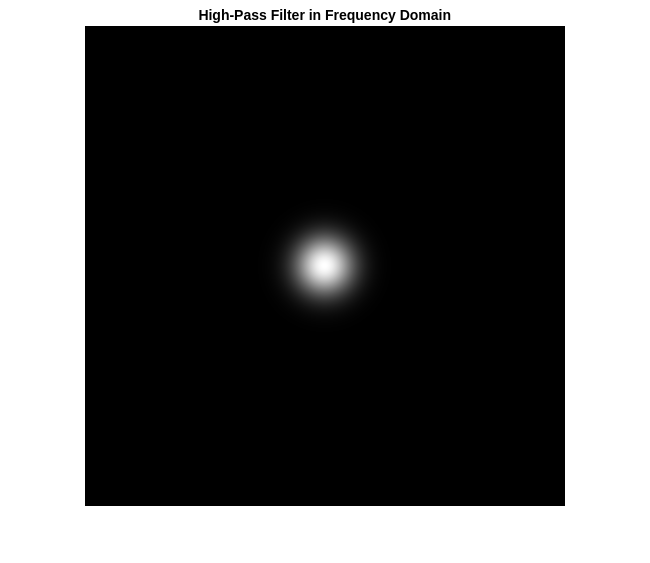


% First Image High Freq Filter
[filteredmg_high2,gaussion_high_mg2] = HPFilter(20, Y_pc, s2);

figure
imshow(gaussion_high_mg2,[])
title("High-Pass Filter in Frequency Domain")


figure
subplot(1,2,1)
imshow(mg_pc, [])
title("Inital Grayscale Image")
subplot(1,2,2)
imshow(filteredmg_high2, [])

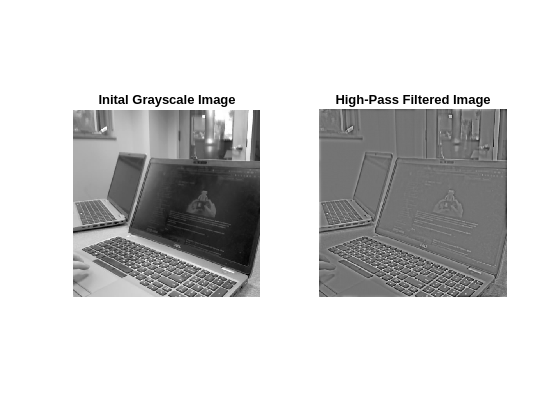

title("High-Pass Filtered Image")

Comparison between spatial and frequency domain filtering:

% gaussian noise spatial filtering
Gnoisemg = imnoise(mg, "gaussian");
noiseY = fft2(Gnoisemg, 1200, 1200);

% LP filtering (freq domain)
[LPfiltC, gaussian_low_c] = LPFilter(100, Y, s);
Gclear = imgaussfilt(Gnoisemg,2);

figure
subplot(1,3,1)
imshow(Gnoisemg)
title("Noisy Original")
subplot(1,3,2)
imshow(LPfiltC,[])

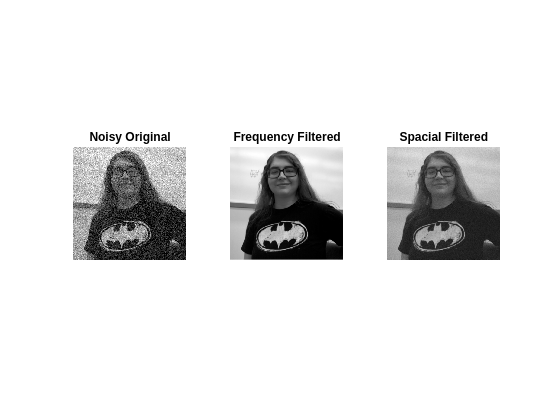

title("Frequency Filtered")
subplot(1,3,3)
imshow(Gclear)
title("Spacial Filtered")



% salt & pepper noise spatial filtering
Gnoisemg_pc = imnoise(mg_pc, "salt & pepper");
noiseY_pc = fft2(Gnoisemg_pc, 480, 480);

% LP filtering (freq domain)
[LPfiltC_pc, gaussian_low_c_pc] = LPFilter(100, Y_pc, s2);
Gclear_pc = medfilt2(Gnoisemg_pc);

figure
subplot(1,3,1)
imshow(Gnoisemg_pc)
title("Noisy Original")
subplot(1,3,2)
imshow(LPfiltC_pc,[])

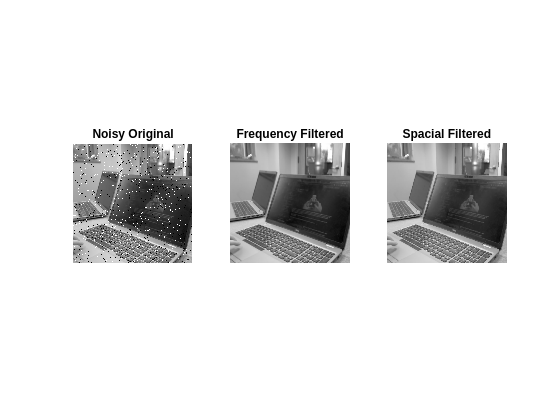

title("Frequency Filtered")
subplot(1,3,3)
imshow(Gclear_pc)
title("Spacial Filtered")

Two different types of noises, Gaussian and Salt & Pepper, are added to the two images. 

For the Gaussian-noise-induced image, we compared the effect of applying a low-pass filter in the frequency domian (sigma = 100) and the Gaussian Filter function in MATLAB. The result shows that the frequency domain filter is significantly better in removing low frequency noises, resulting in a clear white background and nice contrast between then white icon and Miranda's black shirt. 

For the Salt & Pepper-noise-induced image, we compared the effect of applying a low-pass filter in the frequency domian (sigma = 50) and the Median Filter function in MATLAB. There is little difference between the two - both successfully removes the spiked pixel values in the original image. 

** 2. Deconvolution and** **Deblurring.** MATLAB and other programming platforms allow you to do a blind deconvolution or use some pre-designed functions to achieve deblurring. Try out the given sample code [trydeconv.m](https://canvas.olin.edu/courses/819/files/186973?wrap=1) on some of your images. 

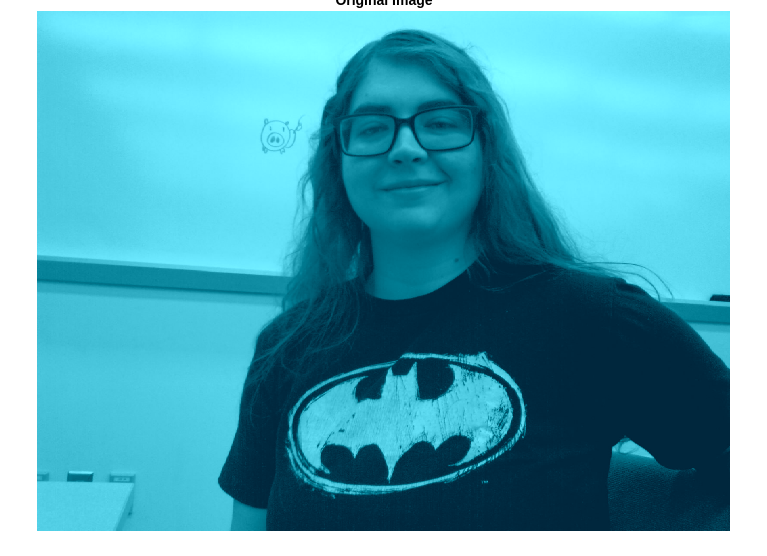

% create blurred image by convolving with PSF
I = imread('../images/IMAGE012.jpg');
figure; imshow(I); title('Original Image');

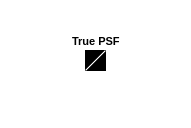


PSF = fspecial('motion',28,45);% Create the PSF
figure; imshow(PSF,[]); title('True PSF');

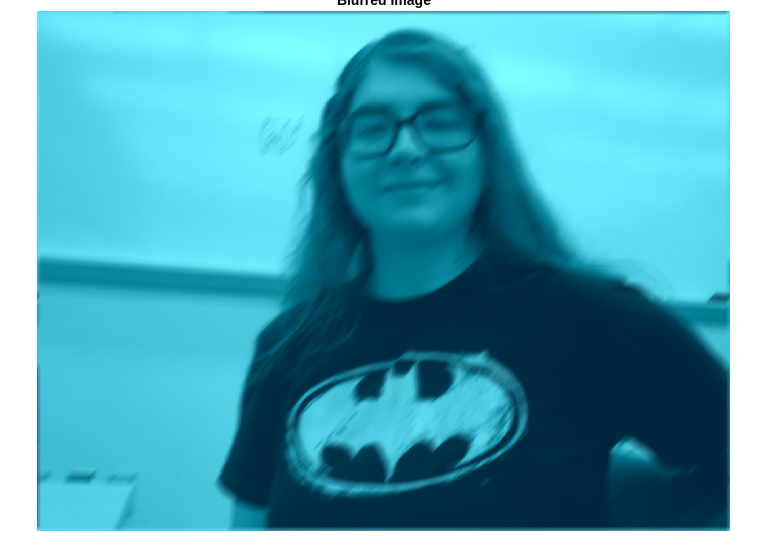


Blurred = imfilter(I,PSF,'circ','conv');% Simulate the blur
figure; imshow(Blurred); title('Blurred Image');

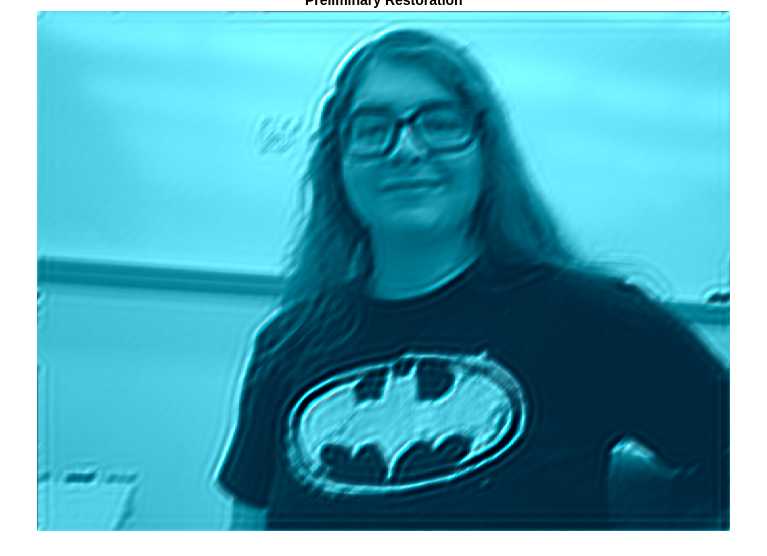


% deconvolve with "blindly"
INITPSF = ones(size(PSF));
[J P]= deconvblind(Blurred,INITPSF,10);
figure; imshow(J); title('Preliminary Restoration');

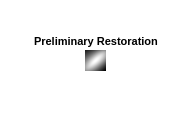

figure; imshow(P,[]);
title('Preliminary Restoration');

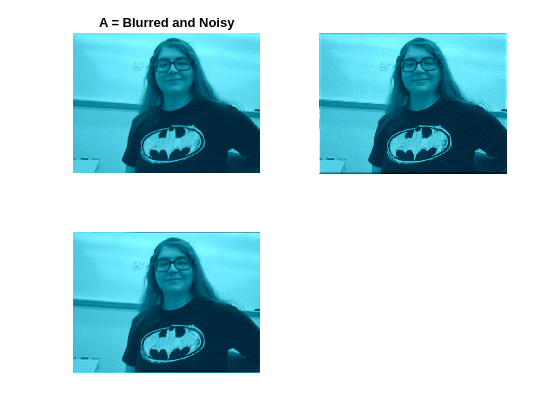


% gaussian 
PSF2 = fspecial('gaussian',7,10);

V = .0001;
BlurredNoisy = imnoise(imfilter(I,PSF2),'gaussian',0,V);
J1= deconvlucy(BlurredNoisy,PSF2);
J2= deconvlucy(Blurred,PSF);

% Display the results.
figure;
subplot(221);imshow(BlurredNoisy);
title('A = Blurred and Noisy');
subplot(222);imshow(J1);
subplot(223);imshow(J2);

What are the pros and cons of these pre-designed functions? Pre-designed functions estimate the blurring kernel for you. Research and explain any two methods of estimating a deblurring kernel without using pre-designed functions? You can use any material available to do your research – youtube videos, research papers, tutorials – whatever your group chooses. **(30 points). **(might be helpful to review [MATLAB summary of blind deconvolutionLinks to an external site.](https://www.mathworks.com/help/images/ref/deconvblind.html)).

**3. Histogram equalization.** Use histogram equalization as an image enhancement technique on two images of your choice. If you used inbuilt functions (e.g. histeq in MATLAB, or cv2.equalizeHist() in OpenCV), did you see any limitations of these inbuilt functions? If yes, what are they? **(10 points). **(sample histogram equalization code: [imenhance.m](https://canvas.olin.edu/courses/819/files/186985?wrap=1))

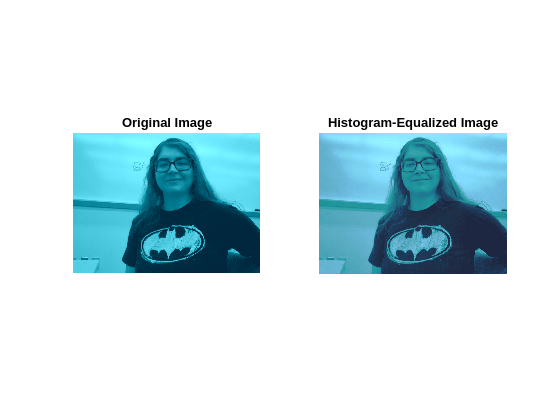

figure
miranda = imread('../images/IMAGE012.jpg');
computer = imread('../images/IMAGE001.jpg');

% First Image
[m,T] = histeq(miranda, 60);
figure
subplot(1,2,1)
imshow(miranda)
title("Original Image")
subplot(1,2,2)
imshow(m)
title("Histogram-Equalized Image")

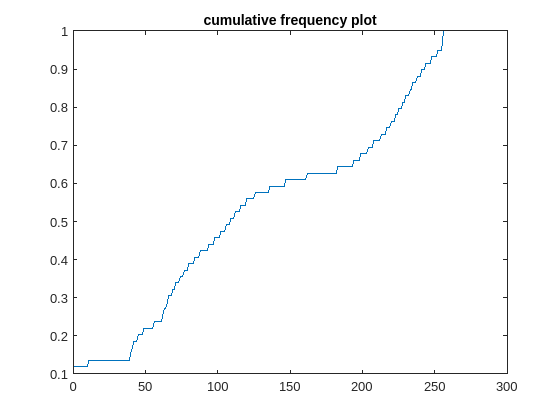


figure
plot(T)
title("cumulative frequency plot")

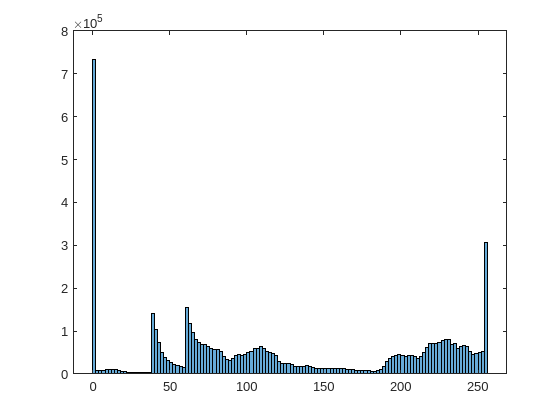

histogram(miranda)

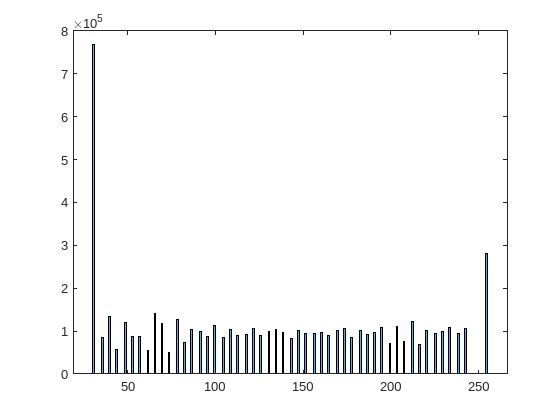

histogram(m)

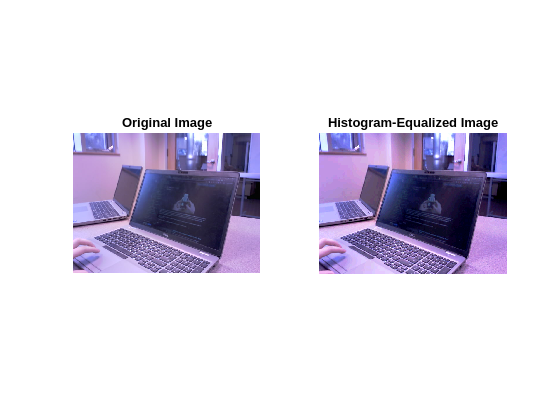


% Second Image 
[hist_pc,T2] = histeq(computer, 30);
figure
subplot(1,2,1)
imshow(computer)
title("Original Image")
subplot(1,2,2)
imshow(hist_pc)
title("Histogram-Equalized Image")

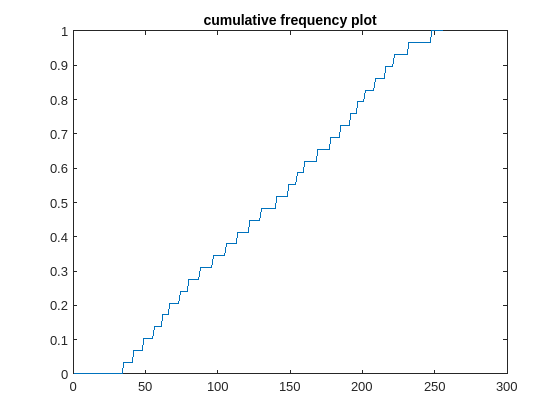


figure
plot(T2)
title("cumulative frequency plot")

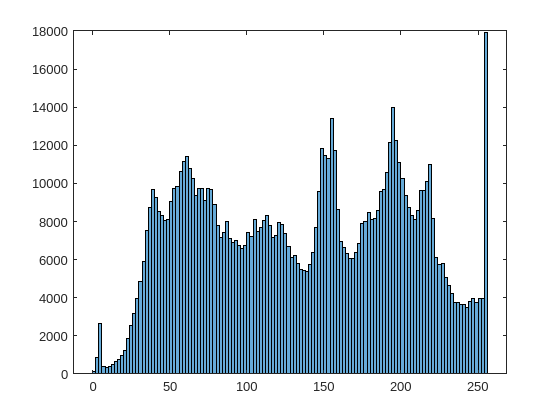

histogram(computer)

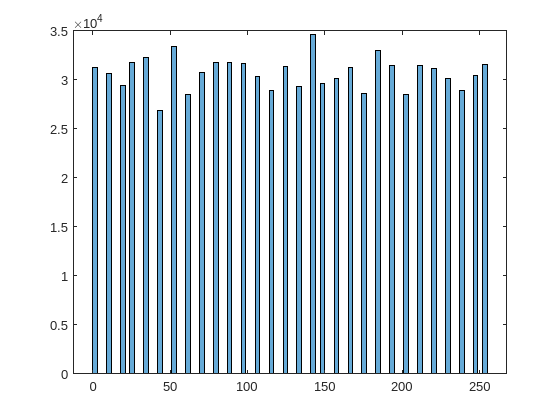

histogram(hist_pc)

In the first case, after applying the histogram equalization technique using MATLAB's in-built `histeq()` function, Miranda's face and hair lose their original contrast with the background. This is unexpected, as histogram equalization is typically used to enhance contrast, especially in "washed-out" images. However, this result highlights a limitation of the `histeq()` function when applied to images where contrast between specific elements needs to be preserved.

In the second image, the `histeq()` function performs well in removing the foggy white fingerprint from the computer screen. The cumulative frequency plot confirms the technique's success, showing a well-distributed, almost perfectly diagonal zigzag line. This demonstrates that while MATLAB's `histeq()` can be effective for certain use cases, such as clearing visual noise, it may not be suitable for images where preserving fine detail contrast is important.

**4. Some more filtering.** You are provided with a code ‘[Frequency_LPF.m](https://canvas.olin.edu/courses/819/files/186868?wrap=1). It implements 3 types of low pass filters in frequency domain – ideal, butterworth and gaussian. Run this code for an image of your choice. Comment on the effects of these filters in your image. Feel free to play around with parameters and those changes to your comments. **(10 points).**

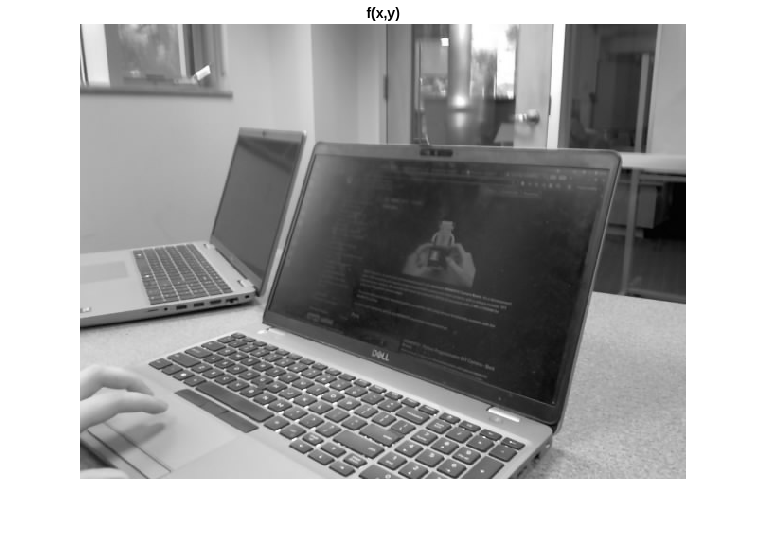

clc
clear all
clf
%%
img = imread('../images/IMAGE001.jpg');
gimg=rgb2gray(img);
imshow(gimg)
title('f(x,y)')

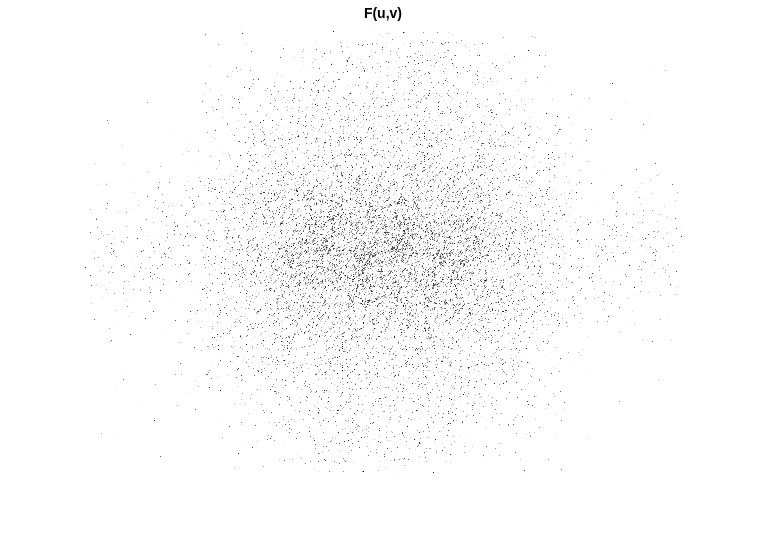

%% Ideal low pass
P=size(gimg);
M=P(1);N=P(2);
F=fft2(gimg,M,N);
%imshow(uint8(abs(fftshift(F))));
imshow(uint8(abs((F))));
title('F(u,v)')

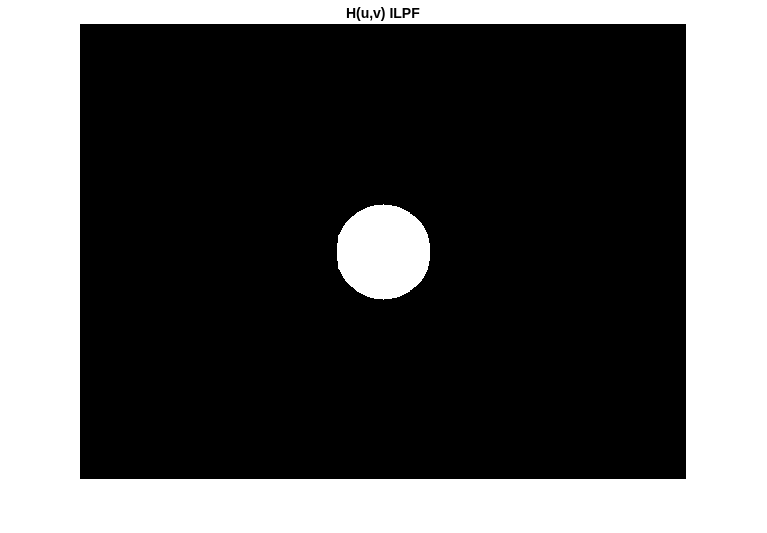

u0=50; %remove freq greater than u0
u=0:(M-1);
v=0:(N-1);
idx=find(u>M/2);
u(idx)=u(idx)-M;
idy=find(v>N/2);
v(idy)=v(idy)-N;
[V,U]=meshgrid(v,u);
D=sqrt(U.^2+V.^2);
H=double(D<=u0);
% display
imshow(abs(fftshift(H)),[]);
title('H(u,v) ILPF')

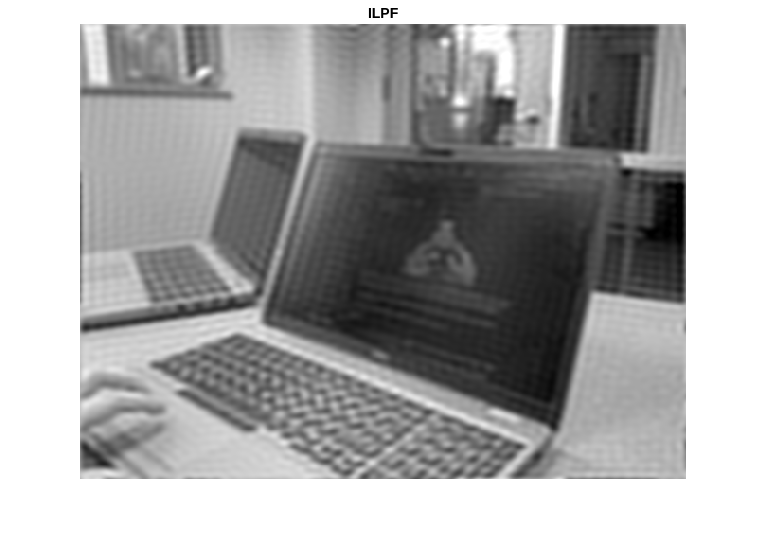

G=H.*F;
gideal=(ifft2(G));
imshow(uint8(gideal))
title('ILPF')

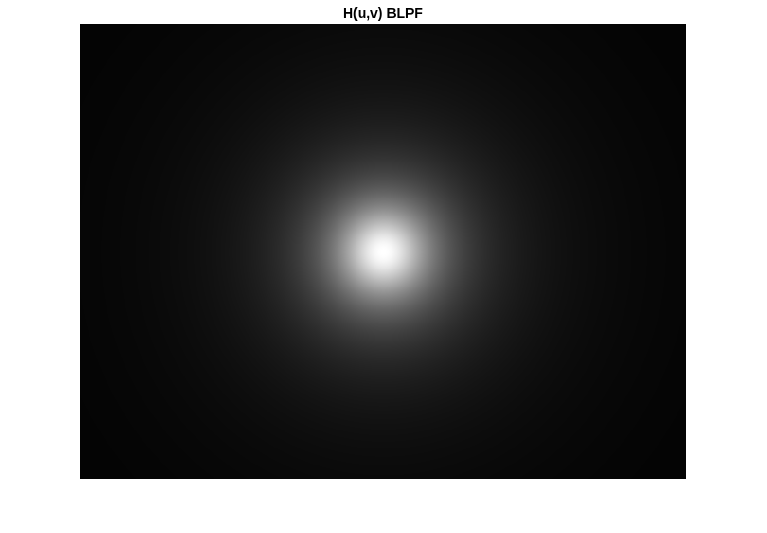

%% Butterworth low pass
n=1; %Butterworth filter of order n
H= 1./(1 + (D./u0).^(2*n));
imshow(abs(fftshift(H)));
title('H(u,v) BLPF')

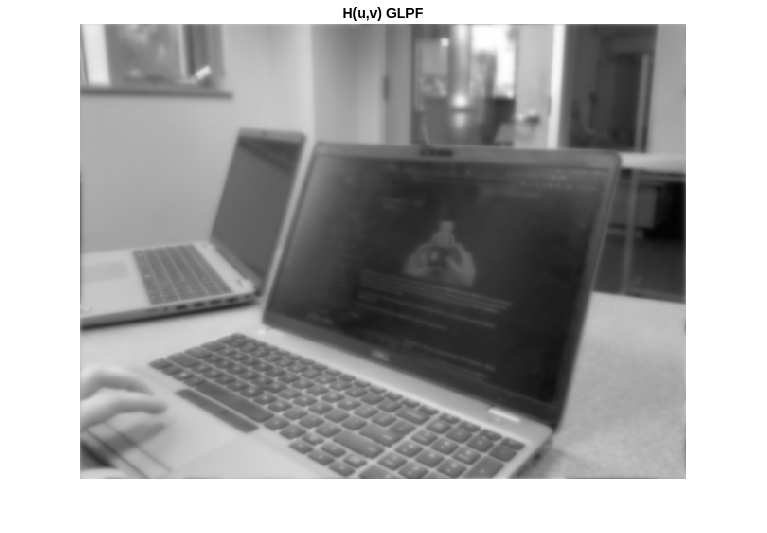

G=H.*F;
gbutter=(ifft2(G));
imshow(uint8(gbutter))
title('BLPF')
%% Gaussian low pass filter
H = exp(-(D.^2)./(2*(u0^2)));
% imshow(abs(fftshift(H)));
title('H(u,v) GLPF')

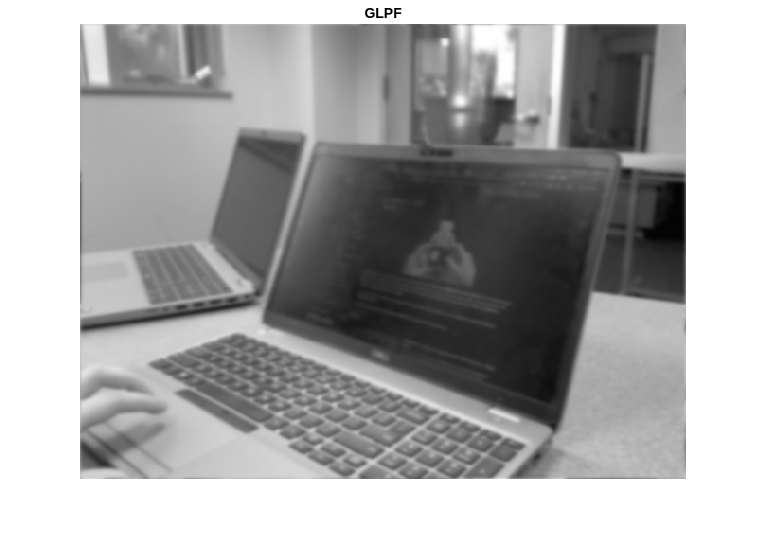

G=H.*F;
ggauss=(ifft2(G));
imshow(uint8(ggauss))
title('GLPF')

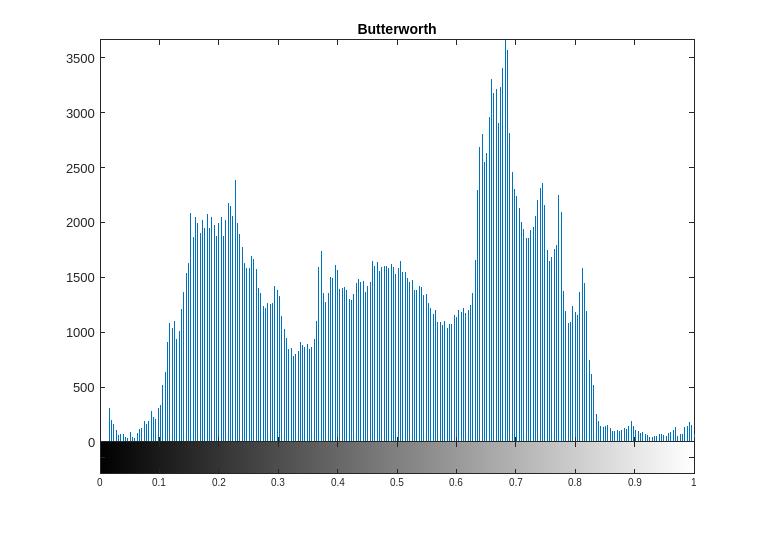


imhist(gbutter/255)
title("Butterworth")

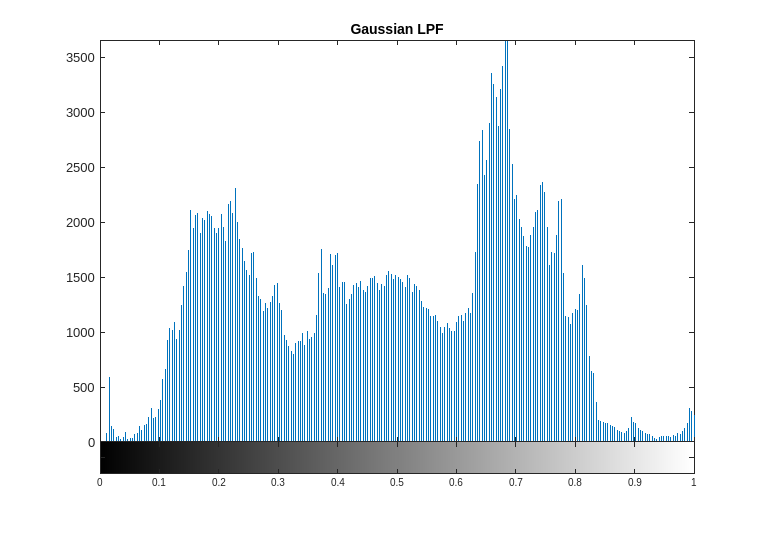

imhist(ggauss/255)
title("Gaussian LPF")

The image resulting from the ideal LPF filter showed a lot of visible artifacts echoing away from edges, likely due to the sharp edge of the filter. 

The butterworth filter and gaussian lowpass filter were a lot more visually similar. The gaussien lpf seemed to preserve a little more contrast than the butterworth. When comparing their histograms, the shapes were also very similar, though some smaller peaks looked a little more prominent in the gaussian histogram than the butterworth.

(Functions used in Part 1 for low-pass and high-pass filtering)

function [img_filt,gauss_2d] = LPFilter(sigma, image, s)
   % create gaussian filter layer
    gauss_2d = zeros(s);
    for i = 1:s
        for j = 1:s
            gauss_2d(i, j) = ( ...
                1/(2*3.14*sigma^2) * ...
                exp(-1/2*((i-s/2)^2+(j-s/2)^2)/sigma^2) ...
                );
        end
    end
    
    % piece-wise multiplication in freq doamine
    filtered = image .* ifftshift(gauss_2d);
    img_filt = ifft2(filtered);
end 


function [img_filt, gauss_2d] = HPFilter(sigma, image, s)
    gauss_2d = zeros(s);
    for i = 1:s
        for j = 1:s
            gauss_2d(i, j) = ( ...
                1/(2*3.14*sigma^2) * ...
                exp(-1/2*((i-s/2)^2+(j-s/2)^2)/sigma^2) ...
                );
        end
    end

    % shift and recenter to get the inverse of 
    % low-pass filter gassian freq image
    mid = (max(gauss_2d(:)) - min(gauss_2d(:)))/2;
    gauss_I = -1*(gauss_2d - mid)+mid;
    filtered = image .* ifftshift(gauss_I);
    img_filt = ifft2(filtered);
end 

